% system
A = [0,1;0,0];
B1 = [3,1;-1,2];
B2 = [0;1];

% z(t)
C2 = [0,0;5,3;1,2];
D2 = [3;0;0];

% conditional test
C2'*D2 == 0

ans = 2×1 logical array
   1
   1


det(D2'*D2)

ans = 9

rank(ctrb(A,B2))

ans = 2

rank(obsv(A,C2))

ans = 2


% H_2 control
Q = icare(A,B2,C2'*C2,D2'*D2,0,eye(2,2),0)

Q =    16.6667   15.2971
   15.2971   19.8078


K = -inv(D2'*D2)*B2'*Q

K =    -1.6997   -2.2009



% W(w->z)
syms s real;
W_s = (C2+D2*K)*inv(s*eye(2,2)-A-B2*K)*B1;
[N11, D11] = numden(W_s(1,1));
[N12, D12] = numden(W_s(1,2));
[N21, D21] = numden(W_s(2,1));
[N22, D22] = numden(W_s(2,2));
WN11  = coeffs(N11, 'All');
WD11  = coeffs(D11, 'All');
WN12  = coeffs(N12, 'All');
WD12  = coeffs(D12, 'All');
WN21  = coeffs(N21, 'All');
WD21  = coeffs(D21, 'All');
WN22  = coeffs(N22, 'All');
WD22  = coeffs(D22, 'All');

W = [
    tf(double(WN11), double(WD11)), tf(double(WN12), double(WD12));
    tf(double(WN21), double(WD21)), tf(double(WN22), double(WD22));
    ]

W =
 
  From input 1 to output...
              -5.873e16 s + 3.445e16
   1:  ------------------------------------
       6.755e15 s^2 + 1.487e16 s + 1.148e16
 
               8.106e16 s + 8.59e16
   2:  ------------------------------------
       6.755e15 s^2 + 1.487e16 s + 1.148e16
 
  From input 2 to output...
              -1.237e17 s - 6.889e16
   1:  ------------------------------------
       6.755e15 s^2 + 1.487e16 s + 1.148e16
 
              7.431e16 s + 1.074e17
   2:  ------------------------------------
       6.755e15 s^2 + 1.487e16 s + 1.148e16
 
Continuous-time transfer function.




% H_2 norm of transfer fuction
h_2 = norm(W)

h_2 = 15.0431


% H_inf norm of transfer fuction
h_inf = getPeakGain(W)

h_inf = 14.7160

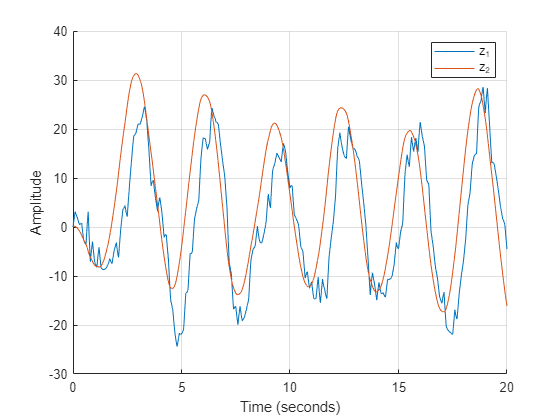


% ampW = bodeplot(W);
% setoptions(ampW,'FreqScale','linear','MagUnits','abs','Grid','on','PhaseVisible','off','IOGrouping','all');
% xlim([0 10]);
% 
% sinValW = sigmaplot(W);
% setoptions(sinValW,'FreqScale','linear','MagUnits','abs','Grid','on');
% xlim([0 10]);

figure; %входные воздействия
grid on;
hold on;
plot(out.z.Time, out.z.Data(:,1))
plot(out.z.Time, out.z.Data(:,2))
xlabel("Time (seconds)"), ylabel("Amplitude")
legend("z_1", "z_2")

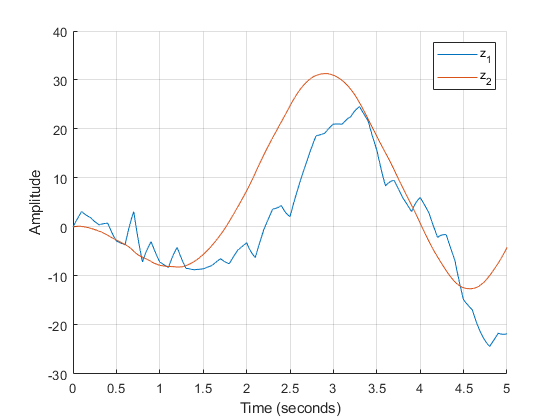

figure; %входные воздействия
grid on;
hold on;
plot(out.z1.Time, out.z1.Data(:,1))
plot(out.z1.Time, out.z1.Data(:,2))
xlabel("Time (seconds)"), ylabel("Amplitude")
legend("z_1", "z_2")
xlim([0 5])